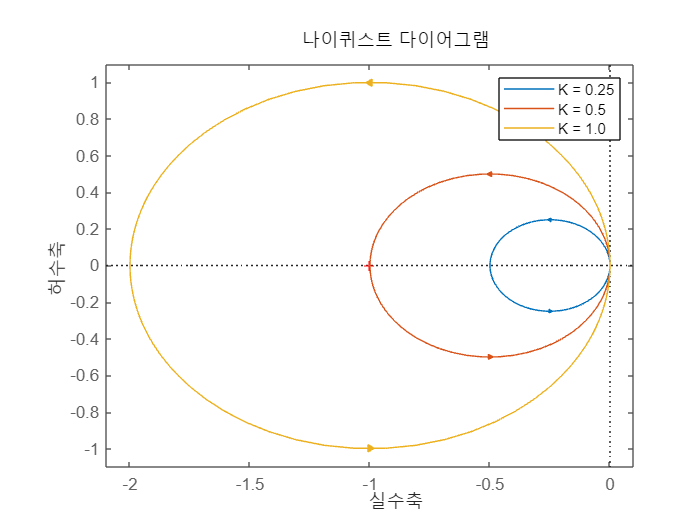

clear all

s = tf('s');
G1 = 0.25/(s-0.5);
G2 = 0.5/(s-0.5);
G3 = 1.0/(s-0.5);
nyquist(G1,G2,G3)
axis([-2.1 0.1 -1.1 1.1])
legend('K = 0.25','K = 0.5','K = 1.0')

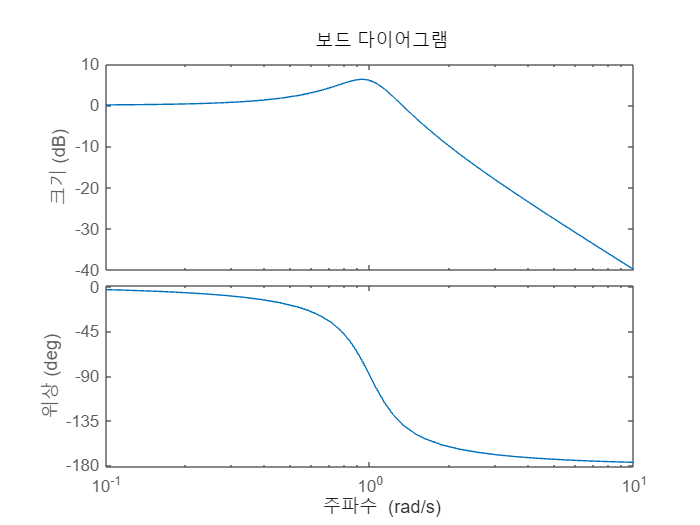

s = tf('s');
G = 1/(s^2 + 0.5*s + 1);
bode(G)

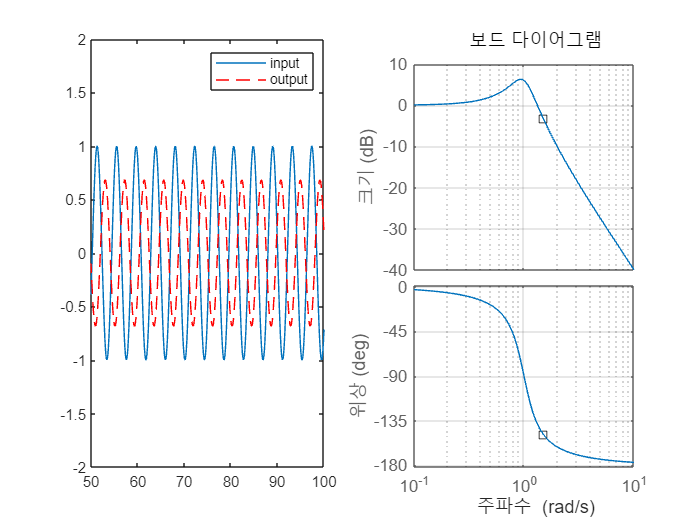

G = 1/(s^2 + 0.5*s + 1);
w =1.5;
t = 0:0.1:100;
u = sin(w*t);
[y, t] =lsim(G,u,t);

f1 = figure;
subplot(1,2,1)
plot(t,u,t,y,'r--')
legend('input','output')
axis([50 100 -2 2])

subplot(1,2,2)
bode(G,w,'ks')
grid
hold on;
bode(G,{0.1,10});

clf(f1);

bw = bandwidth(G) % cutoff frequency (-3db기준)

bw = 1.4839

bw_5 = bandwidth(G,-10) % (-10db기준)

bw_5 = 2.0000

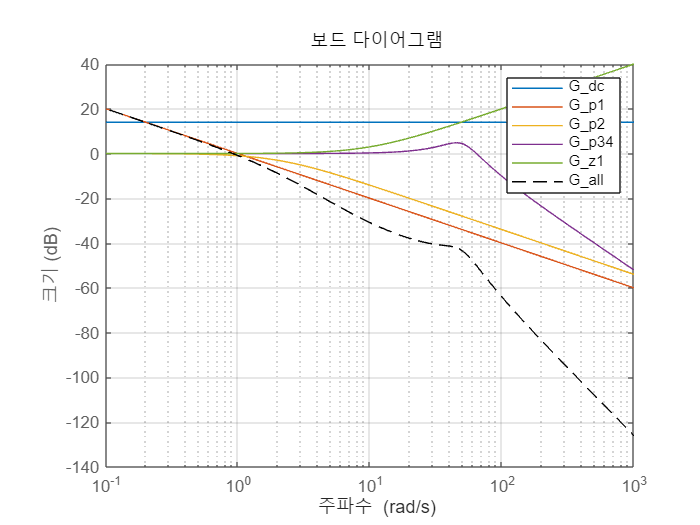

% 더 복잡한 bode plot 그리기
clearvars;
f1 = figure;
s = tf('s');

G_dc = tf(5);
G_p1 = 1/s;
G_p2 = 1/(0.5*s + 1);
G_p34 = 1/(s^2/2500 + s*0.6/50 + 1);
G_z1 = 0.1*s + 1;
G_all = G_p1*G_p2*G_p34*G_z1;

bodemag(G_dc);
grid;
hold on;
legend();
bodemag(G_p1);
bodemag(G_p2);
bodemag(G_p34);
bodemag(G_z1);
bodemag(G_all,'--k');

bw = bandwidth(G_all)

bw = NaN

clf(f1);